## **SIO 207A HW-7**

Ruipu Ji

An IIR low pass filter is desired with the same characteristics as the previously redesigned FIR decimation filter. Specifically, the filter should have an analog passband cutoff frequency of 50 Hz and an analog stopband frequency of 75 Hz. For these critical frequencies, the 64-tap FIR filter achieved a passband ripple of 0.2 dB and a stopband attenuation or sidelobe level of 32.8 dB. Three IIR low pass filters are to be designed using these as the desired specifications.

*Initialization and parameters definition:*

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

% Parameter definition.
fs = 1000; % Sampling frequency (Hz).
fc = 50; % Cutoff frequency (Hz).
fstop = 75; % Stopband frequency (Hz).
Rp = 0.2; % Passband ripple (dB).
Rs = 32.8; % Stopband attenuation (dB).

#### I. Butterworth IIR Filter Design

*Using a Butterworth filter design algorithm, design the required IIR low pass filter:*

% Butterworth filter design.
[n, Wn] = buttord(fc/fs, fstop/fs, Rp, Rs); % Returns to the filter order and cutoff frequency.
[b, a] = butter(n, Wn, 'low'); % Returns to the filter coefficients.

*List the order of IIR filter:*

disp(n);

    13



*List the numeritor IIR filter coefficients:*

% Display numerator IIR filter coefficients.
disp(b);

   1.0e-10 *

    0.0001    0.0013    0.0077    0.0281    0.0704    0.1266    0.1689    0.1689    0.1266    0.0704    0.0281    0.0077    0.0013    0.0001



*List the denominator IIR filter coefficients:*

% Display denominator IIR filter coefficients.
disp(a);

    1.0000  -11.5351   61.4864 -200.5262  446.4092 -716.3352  852.3975 -761.5429  510.8129 -254.0616   91.0715  -22.2802    3.3342   -0.2305



*Plot pole/zero diagram of the IIR filter:*

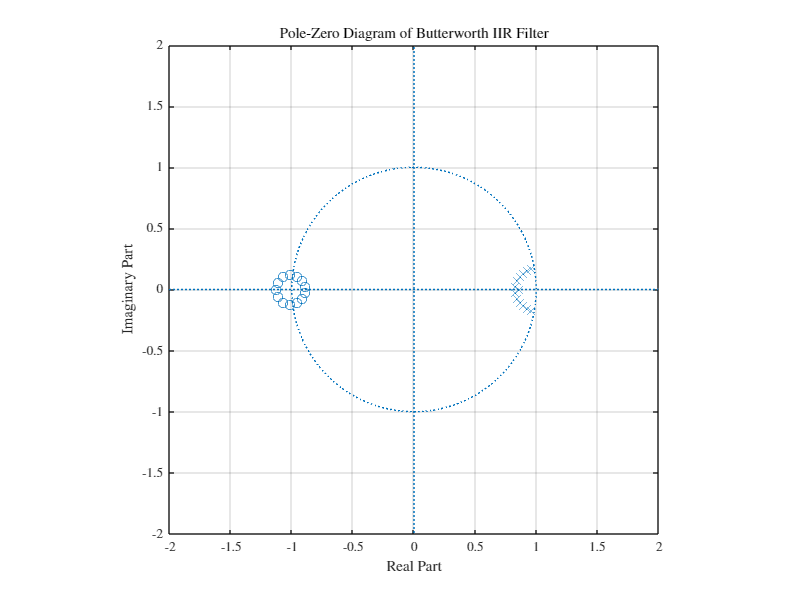

% Plot pole/zero diagram.
figure('Position', [0, 0, 800, 600]);
zplane(b, a);
grid on;
box on;
xlim([-2 2]);
ylim([-2 2]);
xticks(-2:0.5:2);
yticks(-2:0.5:2);
title('Pole-Zero Diagram of Butterworth IIR Filter');

*Plot magnitude (dB) and phase frequency response of the IIR filter:*

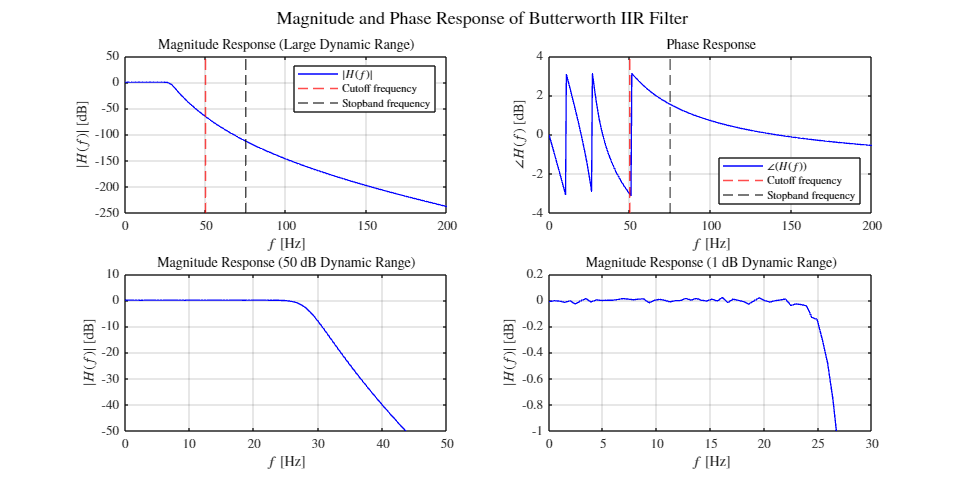

% Calculate frequency response.
[H, f] = freqz(b, a, 1024, fs); % Frequency response.
Magnitude = 20*log10(abs(H)); % Magnitude in dB.
Phase = angle(H); % Phase in radians.

% Plot the results.
figure('Position', [0, 0, 1200, 600]);

subplot(2,2,1); % Magnitude plot with large dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-250 50]);
yticks(-250:50:50);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'northeast');
title('Magnitude Response (Large Dynamic Range)');

subplot(2,2,2); % Phase plot.
hold on;
plot(f, Phase, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-4 4]);
yticks(-4:2:4);
xlabel('$f$ [Hz]');
ylabel('$\angle H(f)$ [dB]');
legend('$\angle (H(f))$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'southeast');
title('Phase Response');

subplot(2,2,3); % Magnitude plot with 50 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([-50 10]);
yticks(-50:10:10);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (50 dB Dynamic Range)');

subplot(2,2,4); % Magnitude plot with 10 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 30]);
xticks(0:5:30);
ylim([-1 0.2]);
yticks(-1:0.2:0.2);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (1 dB Dynamic Range)');

sgtitle('Magnitude and Phase Response of Butterworth IIR Filter');

#### II(A).  Chebyshev Type I IIR Filter Design

*Using a Chebyshev Type I filter design algorithm, design the required IIR low pass filter:*

% Chebyshev Type I filter design.
[n, Wn] = cheb1ord(fc/fs, fstop/fs, Rp, Rs); % Returns to the filter order and cutoff frequency.
[b, a] = cheby1(n, Rp, Wn, 'low'); % Returns to the filter coefficients.

*List the order of IIR filter:*

disp(n);

     7



*List the numeritor IIR filter coefficients:*

% Display numerator IIR filter coefficients.
disp(b);

   1.0e-07 *

    0.0119    0.0831    0.2494    0.4157    0.4157    0.2494    0.0831    0.0119



*List the denominator IIR filter coefficients:*

% Display denominator IIR filter coefficients.
disp(a);

    1.0000   -6.7289   19.4501  -31.3052   30.2998  -17.6351    5.7148   -0.7954



*Plot pole/zero diagram of the IIR filter:*

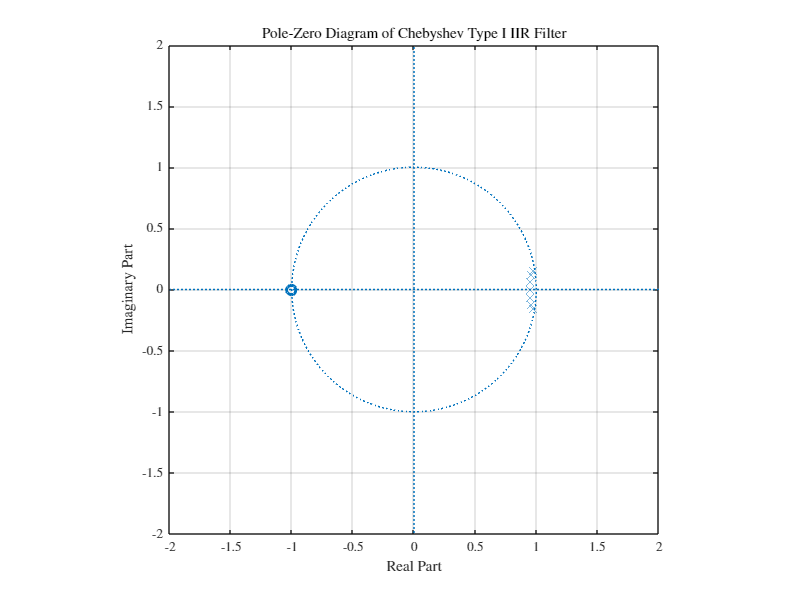

% Plot pole/zero diagram.
figure('Position', [0, 0, 800, 600]);
zplane(b, a);
grid on;
box on;
xlim([-2 2]);
ylim([-2 2]);
xticks(-2:0.5:2);
yticks(-2:0.5:2);
title('Pole-Zero Diagram of Chebyshev Type I IIR Filter');

*Plot magnitude (dB) and phase frequency response of the IIR filter:*

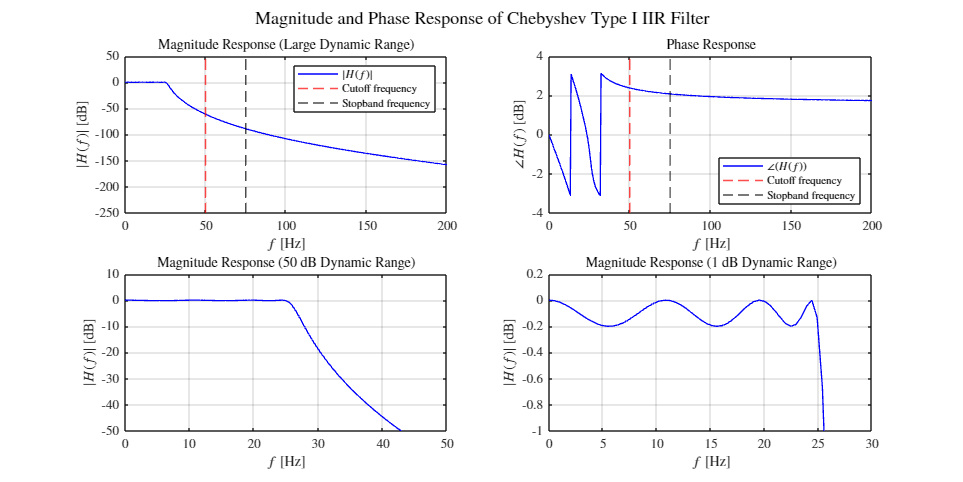

% Calculate frequency response.
[H, f] = freqz(b, a, 1024, fs); % Frequency response.
Magnitude = 20*log10(abs(H)); % Magnitude in dB.
Phase = angle(H); % Phase in radians.

% Plot the results.
figure('Position', [0, 0, 1200, 600]);

subplot(2,2,1); % Magnitude plot with large dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-250 50]);
yticks(-250:50:50);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'northeast');
title('Magnitude Response (Large Dynamic Range)');

subplot(2,2,2); % Phase plot.
hold on;
plot(f, Phase, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-4 4]);
yticks(-4:2:4);
xlabel('$f$ [Hz]');
ylabel('$\angle H(f)$ [dB]');
legend('$\angle (H(f))$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'southeast');
title('Phase Response');

subplot(2,2,3); % Magnitude plot with 50 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([-50 10]);
yticks(-50:10:10);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (50 dB Dynamic Range)');

subplot(2,2,4); % Magnitude plot with 10 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 30]);
xticks(0:5:30);
ylim([-1 0.2]);
yticks(-1:0.2:0.2);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (1 dB Dynamic Range)');

sgtitle('Magnitude and Phase Response of Chebyshev Type I IIR Filter');

#### II(B).  Chebyshev Type II IIR Filter Design

*Using a Chebyshev Type II filter design algorithm, design the required IIR low pass filter:*

% Chebyshev Type I filter design.
[n, Wn] = cheb2ord(fc/fs, fstop/fs, Rp, Rs); % Returns to the filter order and cutoff frequency.
[b, a] = cheby2(n, Rs, Wn, 'low'); % Returns to the filter coefficients.

*List the order of IIR filter:*

disp(n);

     7



*List the numeritor IIR filter coefficients:*

% Display numerator IIR filter coefficients.
disp(b);

    0.0127   -0.0579    0.0984   -0.0531   -0.0531    0.0984   -0.0579    0.0127



*List the denominator IIR filter coefficients:*

% Display denominator IIR filter coefficients.
disp(a);

    1.0000   -5.9746   15.3656  -22.0420   19.0412   -9.9028    2.8701   -0.3575



*Plot pole/zero diagram of the IIR filter:*

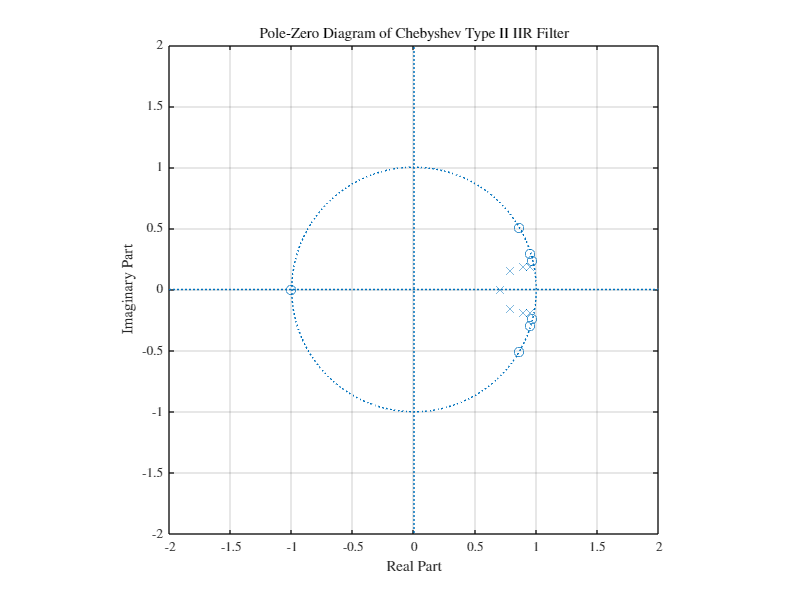

% Plot pole/zero diagram.
figure('Position', [0, 0, 800, 600]);
zplane(b, a);
grid on;
box on;
xlim([-2 2]);
ylim([-2 2]);
xticks(-2:0.5:2);
yticks(-2:0.5:2);
title('Pole-Zero Diagram of Chebyshev Type II IIR Filter');

*Plot magnitude (dB) and phase frequency response of the IIR filter:*

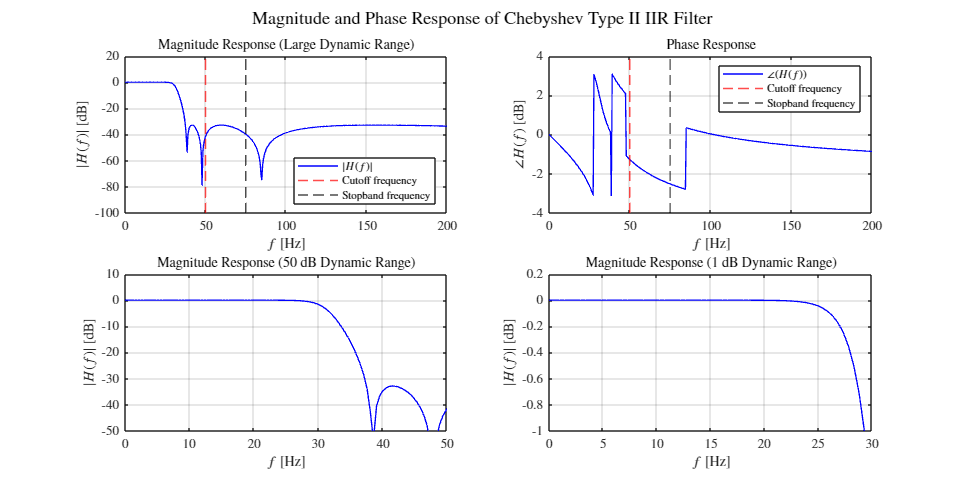

% Calculate frequency response.
[H, f] = freqz(b, a, 1024, fs); % Frequency response.
Magnitude = 20*log10(abs(H)); % Magnitude in dB.
Phase = angle(H); % Phase in radians.

% Plot the results.
figure('Position', [0, 0, 1200, 600]);

subplot(2,2,1); % Magnitude plot with large dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-100 20]);
yticks(-100:20:20);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'southeast');
title('Magnitude Response (Large Dynamic Range)');

subplot(2,2,2); % Phase plot.
hold on;
plot(f, Phase, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:500);
ylim([-4 4]);
yticks(-4:2:4);
xlabel('$f$ [Hz]');
ylabel('$\angle H(f)$ [dB]');
legend('$\angle (H(f))$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'northeast');
title('Phase Response');

subplot(2,2,3); % Magnitude plot with 50 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([-50 10]);
yticks(-50:10:10);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (50 dB Dynamic Range)');

subplot(2,2,4); % Magnitude plot with 10 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 30]);
xticks(0:5:30);
ylim([-1 0.2]);
yticks(-1:0.2:0.2);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (1 dB Dynamic Range)');

sgtitle('Magnitude and Phase Response of Chebyshev Type II IIR Filter');

#### III.  Elliptic IIR Filter Design

*Using a Elliptic filter design algorithm, design the required IIR low pass filter:*

% Elliptic filter design.
[n, Wn] = ellipord(fc/fs, fstop/fs, Rp, Rs); % Returns to the filter order and cutoff frequency.
[b, a] = ellip(n, Rp, Rs, Wn, 'low'); % Returns to the filter coefficients.

*List the order of IIR filter:*

disp(n);

     5



*List the numeritor IIR filter coefficients:*

% Display numerator IIR filter coefficients.
disp(b);

    0.0077   -0.0223    0.0146    0.0146   -0.0223    0.0077



*List the denominator IIR filter coefficients:*

% Display denominator IIR filter coefficients.
disp(a);

    1.0000   -4.7371    9.0146   -8.6124    4.1303   -0.7953



*Plot pole/zero diagram of the IIR filter:*

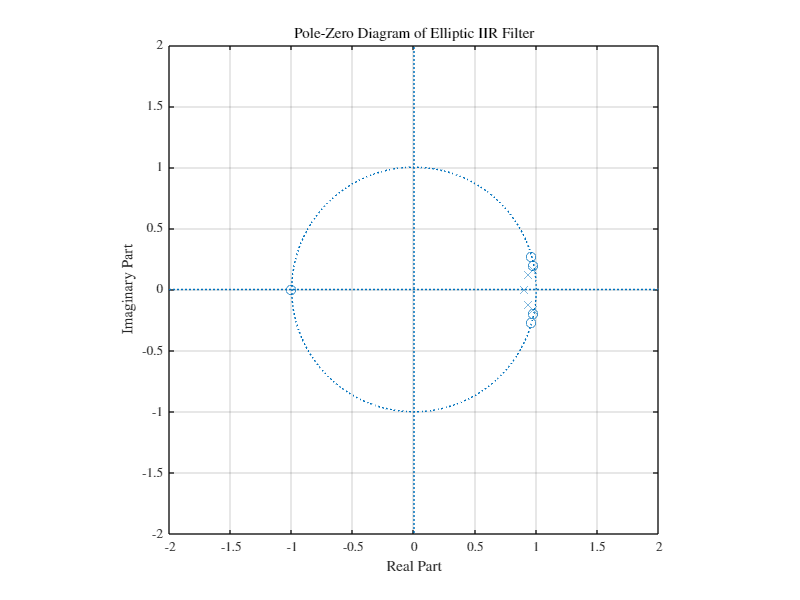

% Plot pole/zero diagram.
figure('Position', [0, 0, 800, 600]);
zplane(b, a);
grid on;
box on;
xlim([-2 2]);
ylim([-2 2]);
xticks(-2:0.5:2);
yticks(-2:0.5:2);
title('Pole-Zero Diagram of Elliptic IIR Filter');

*Plot magnitude (dB) and phase frequency response of the IIR filter:*

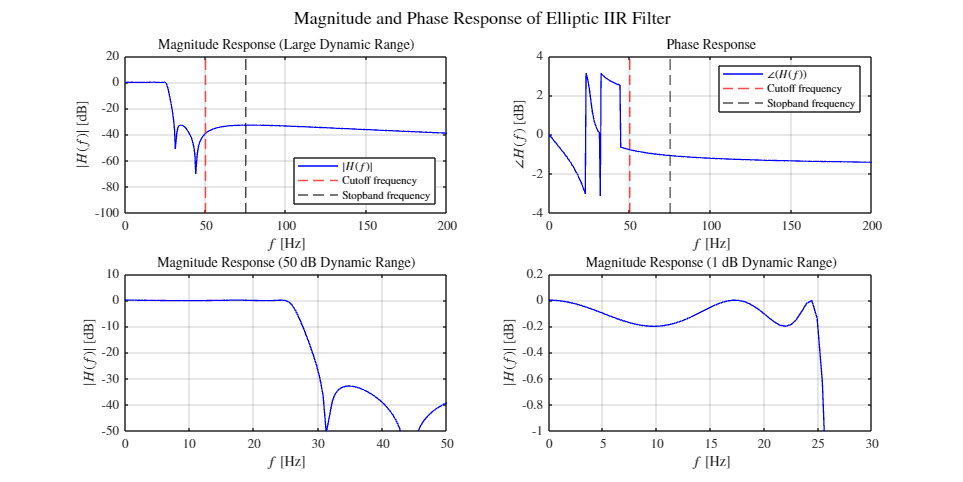

% Calculate frequency response.
[H, f] = freqz(b, a, 1024, fs); % Frequency response.
Magnitude = 20*log10(abs(H)); % Magnitude in dB.
Phase = angle(H); % Phase in radians.

% Plot the results.
figure('Position', [0, 0, 1200, 600]);

subplot(2,2,1); % Magnitude plot with large dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-100 20]);
yticks(-100:20:20);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'southeast');
title('Magnitude Response (Large Dynamic Range)');

subplot(2,2,2); % Phase plot.
hold on;
plot(f, Phase, 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(fstop, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-4 4]);
yticks(-4:2:4);
xlabel('$f$ [Hz]');
ylabel('$\angle H(f)$ [dB]');
legend('$\angle (H(f))$', 'Cutoff frequency', 'Stopband frequency', 'Location', 'northeast');
title('Phase Response');

subplot(2,2,3); % Magnitude plot with 50 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([-50 10]);
yticks(-50:10:10);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (50 dB Dynamic Range)');

subplot(2,2,4); % Magnitude plot with 10 dB dynamic range.
hold on;
plot(f, Magnitude, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 30]);
xticks(0:5:30);
ylim([-1 0.2]);
yticks(-1:0.2:0.2);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
title('Magnitude Response (1 dB Dynamic Range)');

sgtitle('Magnitude and Phase Response of Elliptic IIR Filter');

#### **Comments:**

*The orders of different filters are summarized as follows:*

Butterworth: n = 13

Chebyshev Type I: n = 7

Chebyshev Type II: n = 7

Elliptic: n = 5

*Magnitude reduction**:* Butterworth filter and Chebyshev Type I filter have smoother magnitude reduction with respect to frequenc. Chebyshev Type II filter and Elliptic filter has sharp reduction in magnitude response.

*Response in passband**:* Chebyshev Type II filter has the smoothest response in the passband. Butterworth filter is also relatively smooth in the passband. However, Chebyshev Type I filter and Elliptic filter have quite large ripples within the passband.